# Time Series Forecasting Using Machine Learning

You can watch youtube video where I explained everything [https://youtu.be/CGt2EYjmws0](https://youtu.be/CGt2EYjmws0)

This example shows how to forecast time series data using Machine Learning.

To forecast the values of future time steps of a sequence, you can train a  regression Machine Learning, where the responses are the training sequences with values shifted by one time step. That is, at each time step of the input sequence, the Machine Learning learns to predict the value of the next time step.

This example uses the data set `covid-19 patients of India`. The example trains an Machine Learning Model to forecast the number of covid-19  cases given the number of cases in previous days.

## Load Sequence Data

Read the example data. Corona contains a single time series, with time steps corresponding to days and values corresponding to the number of cases. The output is a column array, where each element is a single time step.

## Load Sequence Data

Read table and Extract after cured data

aa=readtable('Corona.xlsx');

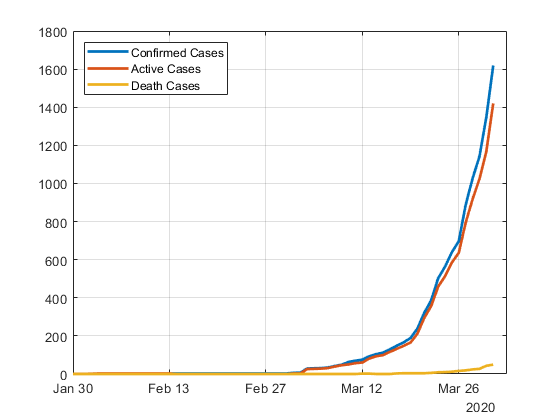

time=aa.Date;
confirmed=aa.Confirmed;
Active_cases=aa.After_Cured-aa.Death;
figure,
plot(time,confirmed,'LineWidth',2)
hold on
plot(time,Active_cases,'LineWidth',2)
plot(time,aa.Death,'LineWidth',2)
hold off
legend('Confirmed Cases','Active Cases','Death Cases','location','northwest')
grid on

**Partition the training and test Active_cases. Train on the first 90% of the sequence and test on the last 10%.**

To forecast the values of future time steps of a sequence, specify the responses to be the training sequences with values shifted by one time step. That is, at each time step of the input sequence, the Machine Learning learns to predict the value of the next time step.

numTimeStepsTrain = floor(0.9*numel(Active_cases));
XTrain = Active_cases(1:numTimeStepsTrain);
YTrain = Active_cases(2:numTimeStepsTrain+1);
XTest = Active_cases(numTimeStepsTrain+1:end-1);
YTest = Active_cases(numTimeStepsTrain+2:end);


Prepare Data

dataa=[XTrain YTrain];


### Call Local Function 

trainedModel = trainRegressionModel(dataa);



YPred=trainedModel.predictFcn(XTest);

The training progress plot reports the root-mean-square error (RMSE) calculated from the standardized data. Calculate the RMSE from the unstandardized predictions.

rmse = sqrt(mean((YPred-YTest).^2));

Plot the training time series with the forecasted values.

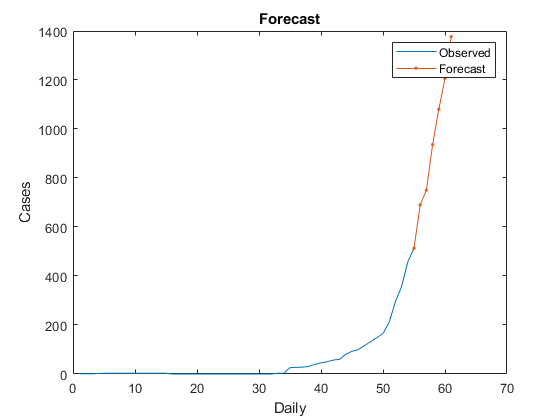


numTimeStepsTest = numel(XTest);
figure
plot(Active_cases(1:numTimeStepsTrain))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[Active_cases(numTimeStepsTrain); YPred],'.-')
hold off
xlabel("Daily")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])

Compare the forecasted values with the test data.

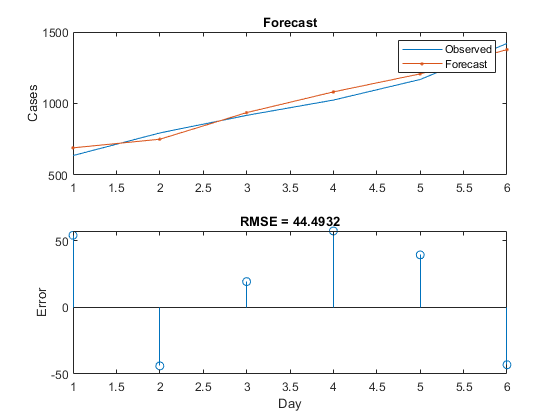

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Day")
ylabel("Error")
title("RMSE = " + rmse)

function [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% [trainedModel, validationRMSE] = trainRegressionModel(trainingData)
% Returns a trained regression model and its RMSE. This code recreates the
% model trained in Regression Learner app. Use the generated code to
% automate training the same model with new data, or to learn how to
% programmatically train models.
%
%  Input:
%      trainingData: A matrix with the same number of columns and data type
%       as the matrix imported into the app.
%
%  Output:
%      trainedModel: A struct containing the trained regression model. The
%       struct contains various fields with information about the trained
%       model.
%
%      trainedModel.predictFcn: A function to make predictions on new data.
%
%      validationRMSE: A double containing the RMSE. In the app, the
%       History list displays the RMSE for each model.
%
% Use the code to train the model with new data. To retrain your model,
% call the function from the command line with your original data or new
% data as the input argument trainingData.
%
% For example, to retrain a regression model trained with the original data
% set T, enter:
%   [trainedModel, validationRMSE] = trainRegressionModel(T)
%
% To make predictions with the returned 'trainedModel' on new data T2, use
%   yfit = trainedModel.predictFcn(T2)
%
% T2 must be a matrix containing only the predictor columns used for
% training. For details, enter:
%   trainedModel.HowToPredict

% Auto-generated by MATLAB on 05-May-2020 11:05:23


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
% Convert input to table
inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2'});

predictorNames = {'column_1'};
predictors = inputTable(:, predictorNames);
response = inputTable.column_2;
isCategoricalPredictor = [false];

% Train a regression model
% This code specifies all the model options and trains the model.
concatenatedPredictorsAndResponse = predictors;
concatenatedPredictorsAndResponse.column_2 = response;
linearModel = fitlm(...
    concatenatedPredictorsAndResponse, ...
    'linear', ...
    'RobustOpts', 'off');

% Create the result struct with predict function
predictorExtractionFcn = @(x) array2table(x, 'VariableNames', predictorNames);
linearModelPredictFcn = @(x) predict(linearModel, x);
trainedModel.predictFcn = @(x) linearModelPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedModel.LinearModel = linearModel;
trainedModel.About = 'This struct is a trained model exported from Regression Learner R2020a.';
trainedModel.HowToPredict = sprintf('To make predictions on a new predictor column matrix, X, use: \n  yfit = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 1 columns because this model was trained using 1 predictors. \nX must contain only predictor columns in exactly the same order and format as your training \ndata. Do not include the response column or any columns you did not import into the app. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
% Convert input to table
inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2'});

predictorNames = {'column_1'};
predictors = inputTable(:, predictorNames);
response = inputTable.column_2;
isCategoricalPredictor = [false];

% Perform cross-validation
KFolds = 5;
cvp = cvpartition(size(response, 1), 'KFold', KFolds);
% Initialize the predictions to the proper sizes
validationPredictions = response;
for fold = 1:KFolds
    trainingPredictors = predictors(cvp.training(fold), :);
    trainingResponse = response(cvp.training(fold), :);
    foldIsCategoricalPredictor = isCategoricalPredictor;
    
    % Train a regression model
    % This code specifies all the model options and trains the model.
    concatenatedPredictorsAndResponse = trainingPredictors;
    concatenatedPredictorsAndResponse.column_2 = trainingResponse;
    linearModel = fitlm(...
        concatenatedPredictorsAndResponse, ...
        'linear', ...
        'RobustOpts', 'off');
    
    % Create the result struct with predict function
    linearModelPredictFcn = @(x) predict(linearModel, x);
    validationPredictFcn = @(x) linearModelPredictFcn(x);
    
    % Add additional fields to the result struct
    
    % Compute validation predictions
    validationPredictors = predictors(cvp.test(fold), :);
    foldPredictions = validationPredictFcn(validationPredictors);
    
    % Store predictions in the original order
    validationPredictions(cvp.test(fold), :) = foldPredictions;
end

% Compute validation RMSE
isNotMissing = ~isnan(validationPredictions) & ~isnan(response);
validationRMSE = sqrt(nansum(( validationPredictions - response ).^2) / numel(response(isNotMissing) ));

end